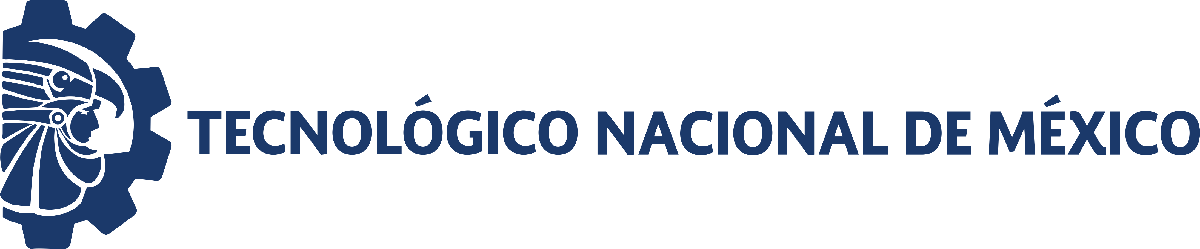                                 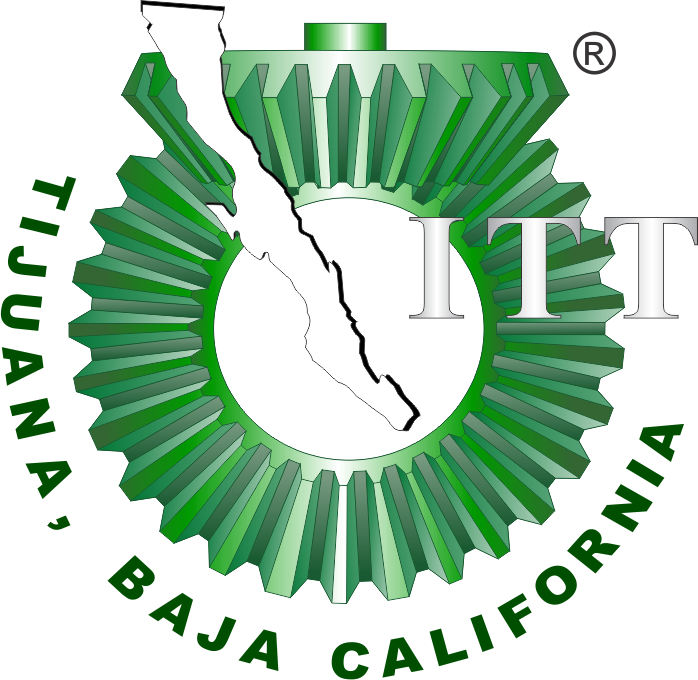

# Práctica dos: Sistema cardiovascular

**Departamento de Ingeniería Eléctrica y Electrónica, Ingeniería Biomédica**

**Tecnológico Nacional de México [TecNM - Tijuana], Blvd. Alberto Limón Padilla s/n, C.P. 22454, Tijuana, B.C., México**

## Información general

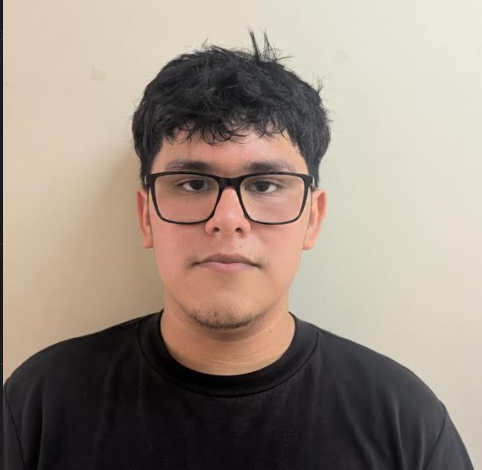

Nombre del alumno: Marco Antonio Garcia Montilla

Número de control: 22211756

Correo institucional: l22211756**@tectijuana.edu.mx**

Asignatura: **Modelado de Sistemas Fisiológicos**

Docente: **Dr. Paul Antonio Valle Trujillo; paul.valle@tectijuana.edu.mx**

## Datos de la simulación

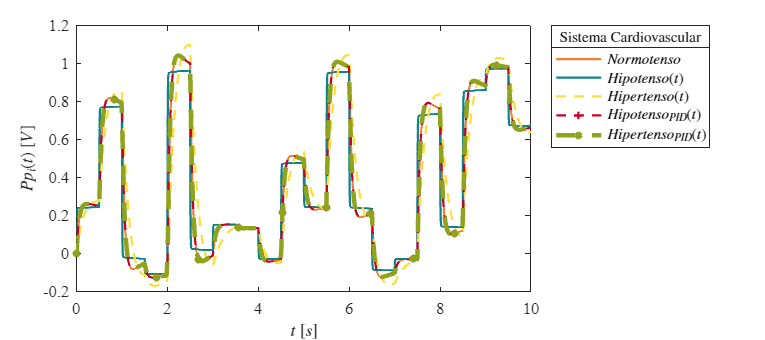

clc; clear; close all; warning('off','all')
tend = '10';
file = 'sistemaP2';
open_system(file);
parameters.StopTime=tend;
parameters.Solver = 'ode23t';
parameters.MaxStep='1E-3';
set_param('sistemaP2/Ppa(t)','Minimum','-0.2');
set_param('sistemaP2/Ppa(t)','Maximum','1');
set_param('sistemaP2/Ppa(t)','Seed','106');
set_param('sistemaP2/Ppa(t)','SampleTime','0.5');
x = sim(file,parameters);
writematrix(x.Ppa,'Signals.xlsx')
plotsignals(x.t,x.Pp0,x.Pp1,x.Pp2,x.Pp3,x.Pp4)

## Datos de la simulación 2da gráfica

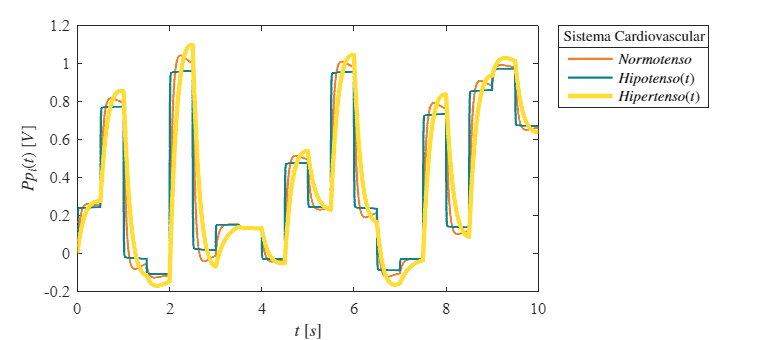

set_param('sistemaP2/Ppa(t)','Maximum','1');
set_param('sistemaP2/Ppa(t)','Seed','106');
set_param('sistemaP2/Ppa(t)','SampleTime','0.5');
x2 = sim(file,parameters);
plotsignals2(x2.t,x2.Pp0,x2.Pp1,x2.Pp2)

## Función:Respuesta a las señales

function plotsignals(t,Pp0,Pp1,Pp2,Pp3,Pp4)
    set(figure(),'Color','w')
    set(gcf,'units','centimeter','position',[1,1,18,8])
    set(gca,'FontName','Times New Roman','FontSize',11)
    hold on;grid off; box on;
    mycolors =[240,128,48;
                15,130,140;
                255,221,51;
                204,0,34;
                143,163,30;
                107,36,12]/255;
    colororder(mycolors)

    p = plot(t,Pp0,'-',t,Pp1,'-',t,Pp2,'--',t,Pp3,'--+',t,Pp4,'--x',...
        'LineWidth',1.5,'MarkerSize',5,'MarkerIndices',1:1000:length(t));
    set(p(5),'LineWidth',3);
    L = legend('$Normotenso$','$Hipotenso(t)$','$Hipertenso(t)$','$Hipotenso_{PID}(t)$','$Hipertenso_{PID}(t)$');
    set(L,'Interpreter','Latex','FontSize',10,'Location','BestOutside','Box','On');
    title(L,'Sistema Cardiovascular','FontSize',10)

    xlabel('$t$ $[s]$','Interpreter','Latex','FontSize',11)
    ylabel('$Pp_i(t)$ $[V]$','Interpreter','Latex','FontSize',11)
    exportgraphics(gcf,['Sistema Cardiovascular PID','.pdf'],'ContentType','vector')
    exportgraphics(gcf,['Sistema Cardiovascular PID','.png'],'ContentType','vector')
end

## Función:Respuesta a las señales 2da

function plotsignals2(t,Pp0,Pp1,Pp2)
    set(figure(),'Color','w')
    set(gcf,'units','centimeter','position',[1,1,18,8])
    set(gca,'FontName','Times New Roman','FontSize',11)
    hold on;grid off; box on;
    mycolors =[240,128,48;
                15,130,140;
                255,221,51;
                204,0,34;
                143,163,30;
                107,36,12]/255;
    colororder(mycolors)

    p = plot(t,Pp0,'-',t,Pp1,'-',t,Pp2,'-',...
        'LineWidth',1.5,'MarkerSize',5,'MarkerIndices',1:1000:length(t));
    set(p(3),'LineWidth',3);
    L = legend('$Normotenso$','$Hipotenso(t)$','$Hipertenso(t)$');
    set(L,'Interpreter','Latex','FontSize',10,'Location','BestOutside','Box','On');
    title(L,'Sistema Cardiovascular','FontSize',10)

    xlabel('$t$ $[s]$','Interpreter','Latex','FontSize',11)
    ylabel('$Pp_i(t)$ $[V]$','Interpreter','Latex','FontSize',11)
    exportgraphics(gcf,['Sistema Cardiovascular','.pdf'],'ContentType','vector')
    exportgraphics(gcf,['Sistema Cardiovascular','.png'],'ContentType','vector')
end